# **模型假设**

1）单次磨损量和法向负载成线性正相关【经文献查阅，在使用大理石时满足此规律】

2）累计磨损量和踩踏次数成线性正相关，且与时间无关（因踩踏产生的磨损远大于因环境影响产生的磨损）

3）人行走时的左右脚发力相同，迈出左脚和右脚的概率统计意义上相同

4）楼梯材质是均质的（后续需要推翻），且可以测量或查阅

5）所有人踩踏时造成的上行磨损都相同（假设取平均体重，平均脚的尺寸，平均滑动距离），所有人踩踏时造成的上行磨损都相同，但上行磨损和下行磨损并不相同。

# **模型建立**

## **1.先建立物理模型**

1）根据英国标准（BS 5395-1）[1]，阶梯宽度 30cm<=L2<=45cm ，故而取L2=40cm，L1取150cm。

2)  由于足底大约长30cm，宽约10cm，且划分为24*8个网格。故而将整个台阶步长选为1.25cm，划分为120*32；

3）选取大理石作为台阶材料，莫氏硬度为2.0-4.3，对比个资料，Hardness可以取H=2Gpa,磨损系数k取160（根据经验自定义）,计算结果与文献[6]中的样本M1对比，发现合理。

4）滑动距离取3mm（自定义）

5）由文献[4],，得到完整的alpha函数，具体可见F.mlx，结果储存在了F.mat中

**1）-4）体现在Archard_time()函数**

**5）的最终结果如下**

*to ljy:这里建议放一下文献[4]的原始图，以及下列我们自己画的图，然后这几幅图可能需要更详细的注释和优化。*

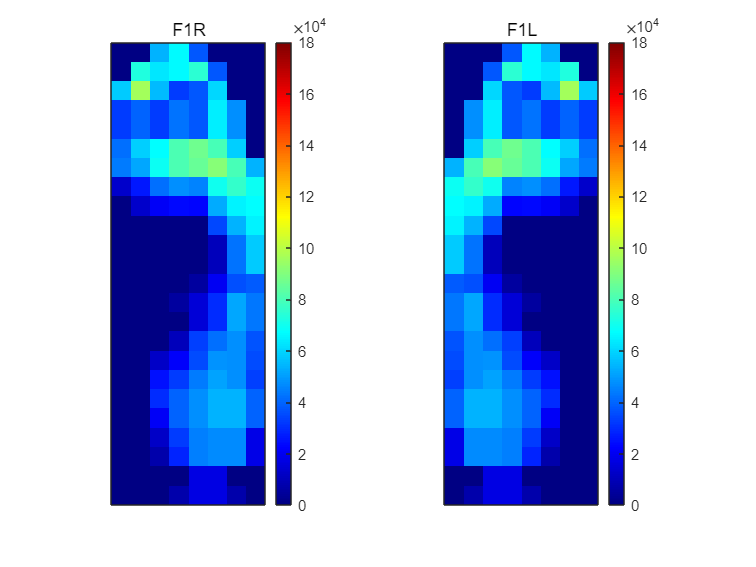

load F.mat;
% 创建热力图
figure();
subplot(1,2,1);
imagesc(F1R);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('F1R');

subplot(1,2,2);
imagesc(F1L);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('F1L');

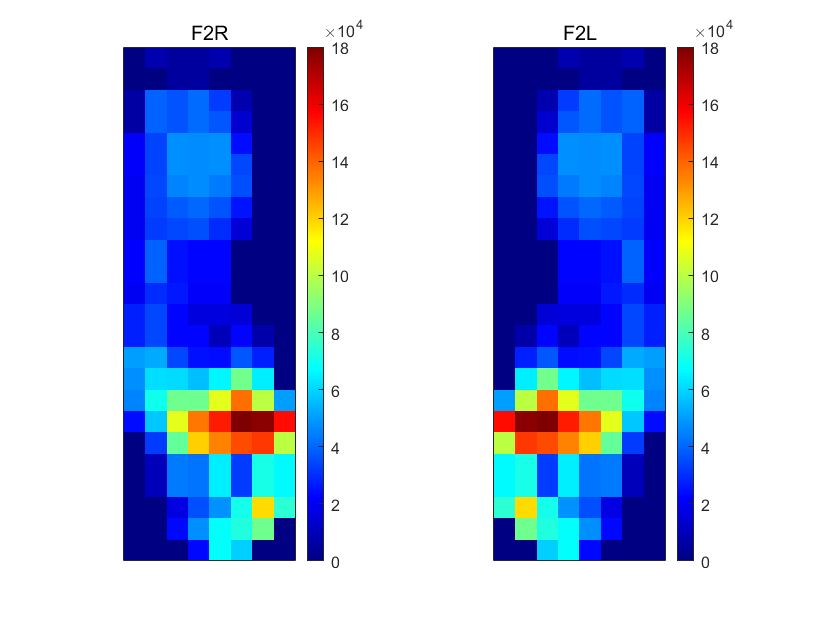


figure();
subplot(1,2,1);
imagesc(F2R);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('F2R');

subplot(1,2,2);
imagesc(F2L);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('F2L');

## **2.然后建立台阶的实际模型**

以下是实验，论文有空档可以写，没有就算了。

值得注意的是，我们将脚的总压力统一化了，这样如果半只脚在外面，其施加的总压力与未踏出时是一样的

clear;clc;
% 设置随机种子
load F.mat;
% 参数设置
L1 = 1.5; % 单位：m
L2 = 0.40; % 单位：m
m = 120; % 网格大小
n = 32; % 网格大小
delta_L = L1/m;
delta_S = delta_L*delta_L;

X=67

X = 67

Y=6

Y = 6

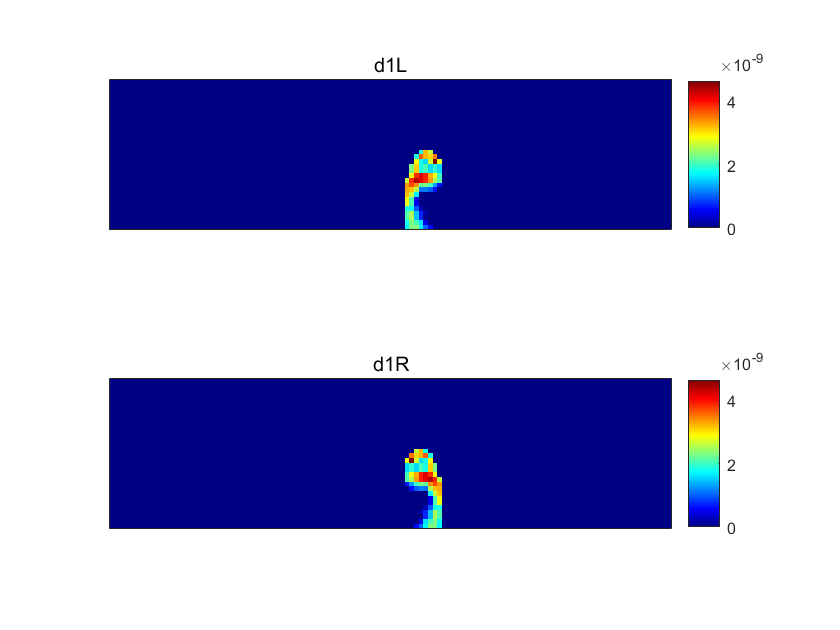

d1L=alphal_1L(Y,X,1,m,n,delta_S,F1L);% 输入y，x坐标
d1R=alphal_1R(Y,X,1,m,n,delta_S,F1R);% 输入y，x坐标

% 创建热力图
figure();
subplot(2,1,1);
imagesc(d1L);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
%caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('d1L');

subplot(2,1,2);
imagesc(d1R);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
%caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('d1R');

d2L=alphal_2L(12,4,1,m,n,delta_S,F2L);% 输入y，x坐标
d2R=alphal_2R(12,4,1,m,n,delta_S,F2R);% 输入y，x坐标

gamma1=sum(sum(d1L))*delta_S;% m^3/次
gamma2=sum(sum(d2L))*delta_S;% m^3/次
save('gamma.mat','gamma1','gamma2','-mat');


g1L=sum(sum(d1L))

g1L = 2.0441e-07

g1R=sum(sum(d1R))

g1R = 2.0441e-07

g2L=sum(sum(d2L))

g2L = 2.5102e-07

g2R=sum(sum(d2R))

g2R = 2.5102e-07

# **一个重要的约束条件+回答第一问**


$$2\gamma_1 * U1 +2 \gamma_2 * U2 =\sum_{x=1}^{m}\sum_{y=1}^{n} \mathbf{d}_{x,y}$$


在上下行比例一定时，可以由该约束条件得到频率。下面的gamma即为单次踩踏（上行or下行）造成的总磨损量

在以下例子中，测量计算出了总的磨损体积（V），从而能够得到具体的约束条件。

load gamma.mat;
rng(42);
f_n=6000;
% 模拟真实数据
d1_true=True(f_n,m,n,delta_S,0.5);
V=sum(sum(d1_true))*delta_S ;
gamma_ratio=gamma2/gamma1;

syms U1 U2
U1=(V-2*gamma2*U2)./(2*gamma1);
var = vpa(U1);
disp(var);

$$3336.8389700688861398672247026144-1.228056174725043013597420975693\,U_{2}$$

# **模型求解和验证**

我们已知

- **楼梯的磨损深度分布情况——通过测量可得**

- **楼梯材料——通过测量和查阅资料可得**

我们选取大理石台阶作为分析案例，具体参数已经在前面的物理模型中体现了，楼梯的磨损深度分布我们假定是i位置的高斯分布函数，并加入一点噪声。

我们需要求解的有

- **人们上行踩踏点的概率分布**

- **人们下行踩踏点的概率分布**

以下是我们遗传算法的验证，具体可见TEST.mlx，结果储存在了f_1.mat中

*to ljy:具体的遗传算法是什么原理可能需要问问贾哥。你这里写的时候要理解程序在做什么并优化图像*

条件：设定人们上行、下行概率相同，在一个月内，共有6000人踏上该台阶

f_n=6000;
load data_11.mat;
% 模拟真实数据
[U1_1_true,U1_2_true,f1_1_true,f1_2_true]=True_Process(f_n,dot1_true,m,n);
[U1_1L,U1_1R,U1_2L,U1_2R,f1_1L,f1_1R,f1_2L,f1_2R]=Estimate_Process(f_n,f1_estimated,m,n);
f1_total_ture=f1_1_true+f1_2_true;
% 根据算法得到分布，并重建数据
d1_theo=d_calculate(m,n,delta_S,f1_1L,f1_1R,f1_2L,f1_2R);
f1_total=f1_1L+f1_1R+f1_2L+f1_2R;
f1_1=f1_1L+f1_1R;
f1_2=f1_2L+f1_2R;

- 对比【真实值】和【经过遗传算法得到分布后的重建值】

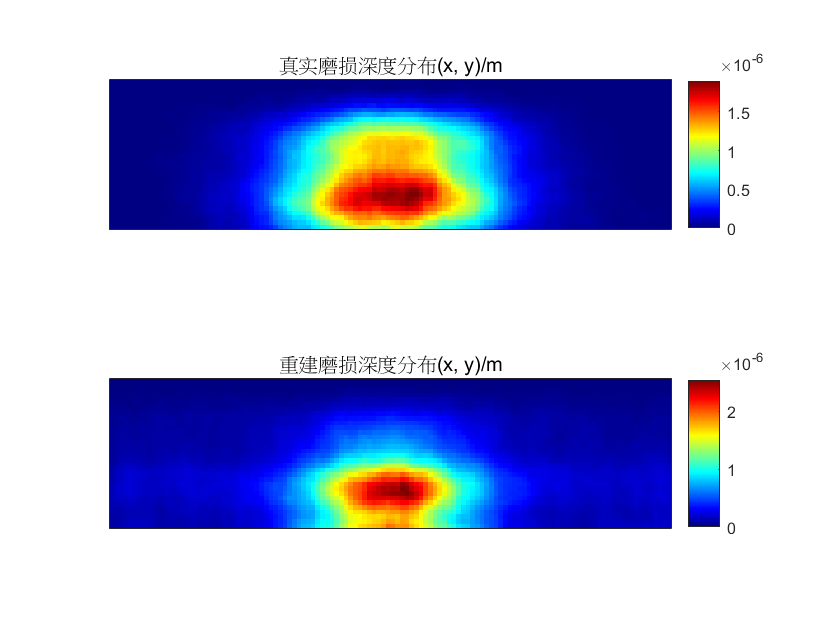

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(d1_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('真实磨损深度分布(x, y)/m');
subplot(2,1,2);
% 可视化模拟数据
imagesc(d1_theo);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('重建磨损深度分布(x, y)/m');

- 分析分布

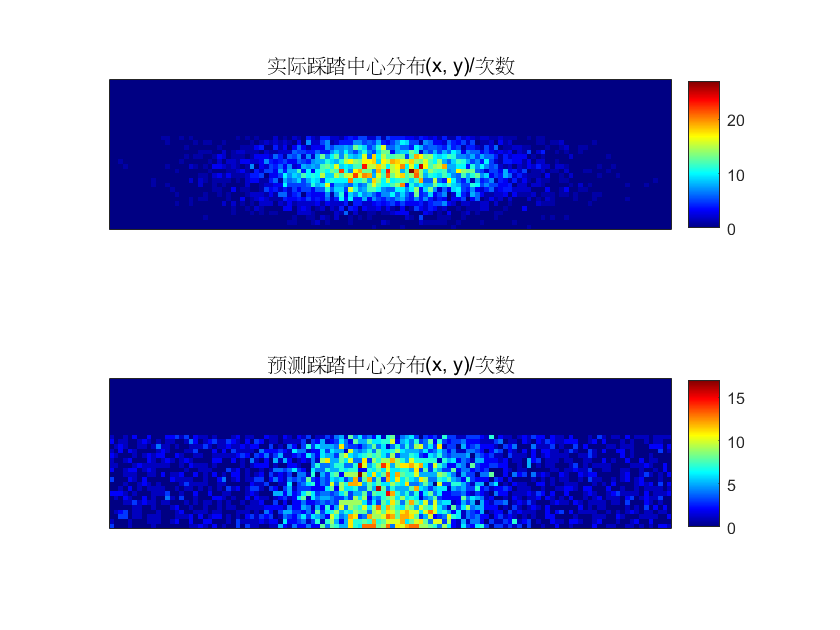

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(f1_total_ture);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('实际踩踏中心分布(x, y)/次数');
subplot(2,1,2);
imagesc(f1_total);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('预测踩踏中心分布(x, y)/次数');

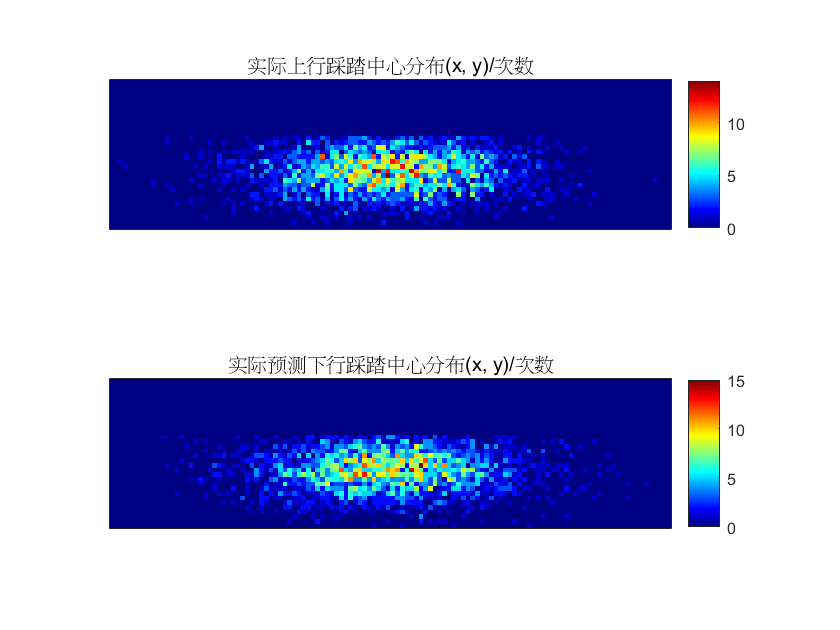

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(f1_1_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('实际上行踩踏中心分布(x, y)/次数');
subplot(2,1,2);
imagesc(f1_2_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('实际预测下行踩踏中心分布(x, y)/次数');

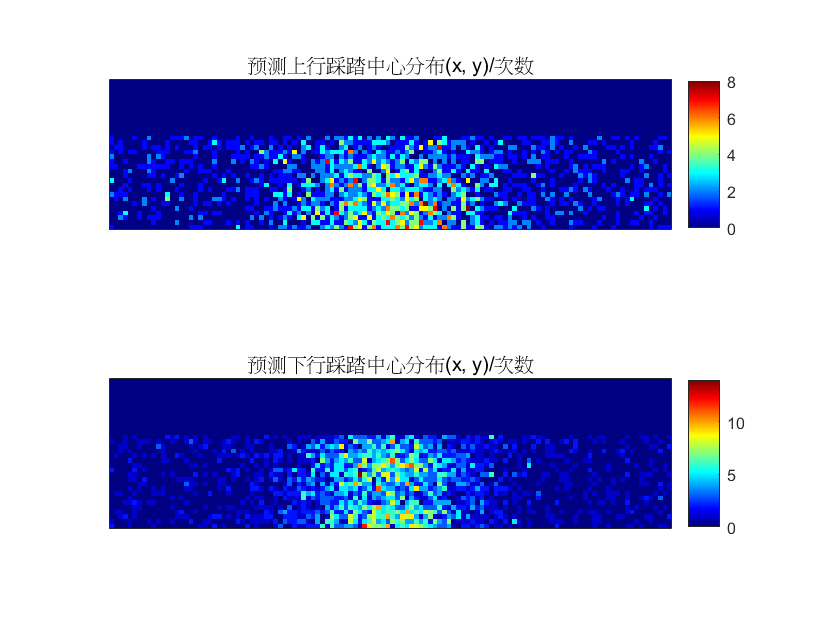

figure();
subplot(2,1,1);
imagesc(f1_1);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('预测上行踩踏中心分布(x, y)/次数');
subplot(2,1,2);
imagesc(f1_2);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('预测下行踩踏中心分布(x, y)/次数');

- 评估误差

***to ljy:也许这里可以画两个饼图，一个是真实的一个时预测的***

% 上行、下行比例误差
U1_1=U1_1L+U1_1R;
U1_2=U1_2L+U1_2R;
r_up_esrimated=U1_1/(U1_1+U1_2); % 上行百分比
r_down_esrimated=U1_2/(U1_1+U1_2); % 下行百分比
ratio_esrimated=U1_1/U1_2%上行：下行

ratio_esrimated = 0.7182


r_up_true=U1_1_true/(U1_1_true+U1_2_true); % 上行百分比
r_downp_true=U1_2_true/(U1_1_true+U1_2_true); % 下行百分比
ratio_true=U1_1_true/U1_2_true %上行：下行

ratio_true = 0.9920


% 重建分布误差
e=d1_true-d1_theo;
e_norm=(sum(sum(abs(e))))/(sum(sum(d1_theo)));
disp(e_norm);

    0.3498



# **回答第一问**

由上述的分布我们可以得到上下行的比例关系，接下来就可以结合约束条件算出频率。

可以看到误差仅为2.0%左右，说明该方法较为有效。

T=30;% 单位：天

% 真实频率
frequncy_true=f_n/T

frequncy_true = 200


% 预测频率
U1_1 = U1_1L + U1_1R;
U1_2 = U1_2L + U1_2R;
r_d_u=U1_2/U1_1 ;%下行：上行
U1=(V/(2*gamma1)) / (gamma_ratio*r_d_u+1);
U2=U1*r_d_u;
frequncy_estimated=2*(U1+U2)/T

frequncy_estimated = 196.3894


% 误差分析
e=(abs(frequncy_true-frequncy_estimated)) / (frequncy_estimated)

e = 0.0184

# **回答第二问**

模型同上，但为了表现出上下行概率差异，

- 情况一：上行下行的概率相同，见上

- 情况二：上行：下行=1：3，见下U21情况

- 情况三：上行：下行=3：1，见下U22情况

以下是具体的过程，具体可见TEST_2_1.mlx和TEST_2_2.mlx，结果储存在了data_21.mat和data_22.mat中

*to ljy:具体的遗传算法是什么原理可能需要问问贾哥，这里你要结合图像，说明上下行概率变化时会发生什么变化*

## **情况二**

条件：设定人们概率有上行：下行=1：3，在一个月内，共有6000人踏上该台阶

f_n=6000;
load data_21.mat
% 根据算法得到分布，并重建数据
[U21_1_true,U21_2_true,f21_1_true,f21_2_true]=True_Process(f_n,dot21_true,m,n);
[U21_1L,U21_1R,U21_2L,U21_2R,f21_1L,f21_1R,f21_2L,f21_2R]=Estimate_Process(f_n,f21_estimated,m,n);
d21_theo=d_calculate(m,n,delta_S,f21_1L,f21_1R,f21_2L,f21_2R);
f21_1=f21_1L+f21_1R;
f21_2=f21_2L+f21_2R;

- 对比【真实值】和【经过遗传算法得到分布后的重建值】

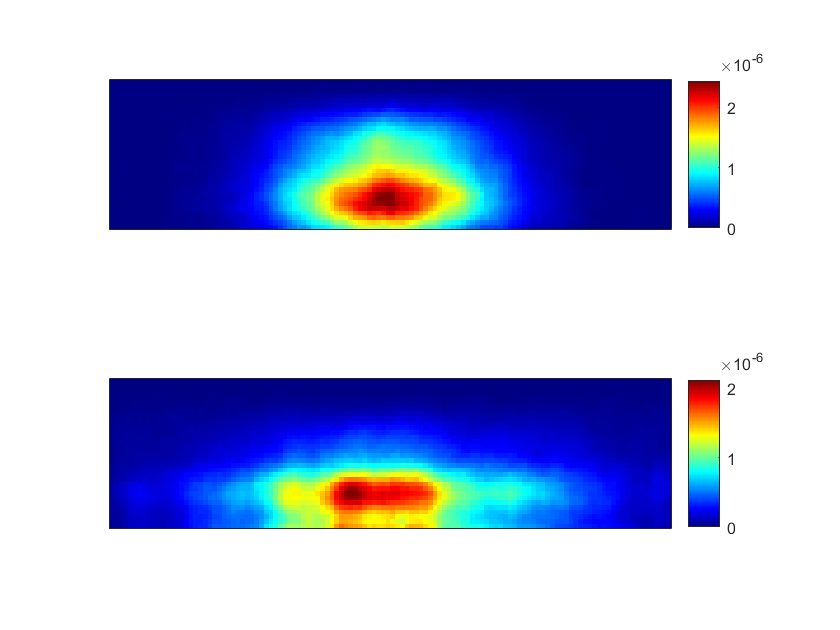

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(d21_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题

subplot(2,1,2);
% 可视化模拟数据
imagesc(d21_theo);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签

% 设置标题


- 评估误差

*to ljy:也许这里可以画两个饼图，一个是真实的一个时预测的*

% 上行、下行比例误差
U21_1=U21_1L+U21_1R;
U21_2=U21_2L+U21_2R;
r_up_esrimated=U21_1/(U21_1+U21_2); % 上行百分比
r_down_esrimated=U21_2/(U21_1+U21_2); % 下行百分比
ratio_esrimated=U21_1/U21_2 %上行：下行

ratio_esrimated = 0.3866


r_up_true=U21_1_true/(U21_1_true+U21_2_true); % 上行百分比
r_downp_true=U21_2_true/(U21_1_true+U21_2_true); % 下行百分比
ratio_true=U21_1_true/U21_2_true %上行：下行

ratio_true = 0.3313


% 磨损深度分布误差
e=d21_true-d21_theo;
e_norm=(sum(sum(abs(e))))/(sum(sum(d21_theo)));
disp(e_norm);

    0.4855



- 分布分析

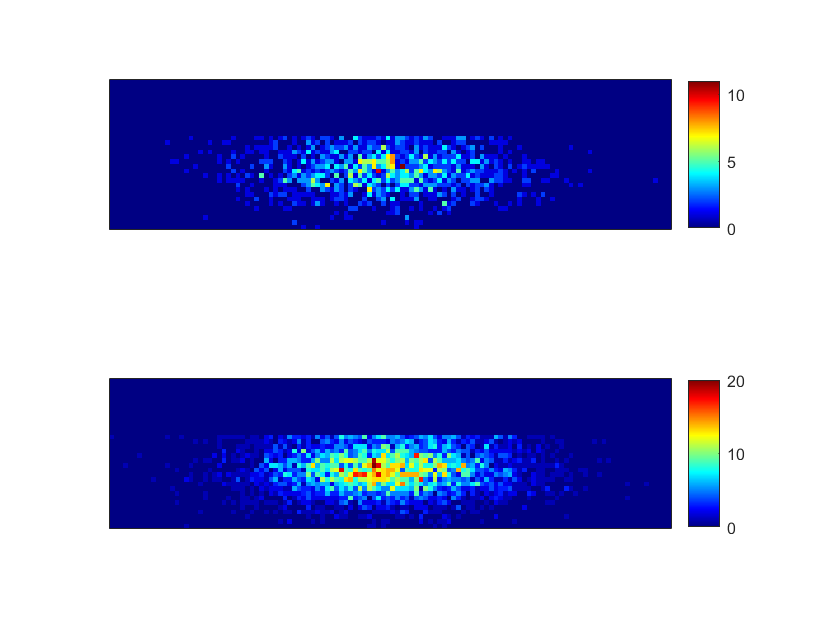

figure();
subplot(2,1,1);
imagesc(f21_1_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题

subplot(2,1,2);
imagesc(f21_2_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签

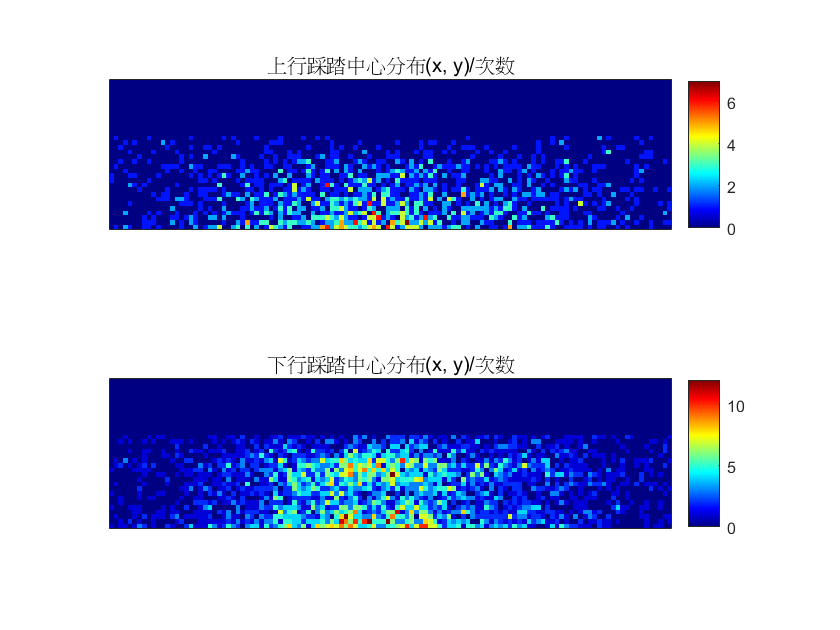

% 设置标题

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(f21_1);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('上行踩踏中心分布(x, y)/次数');
subplot(2,1,2);
imagesc(f21_2);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('下行踩踏中心分布(x, y)/次数');

## **情况三**

条件：设定人们概率有上行：下行=3：1，在一个月内，共有6000人踏上该台阶

f_n=6000;
load data_22.mat
% 根据算法得到分布，并重建数据
[U22_1_true,U22_2_true,f22_1_true,f22_2_true]=True_Process(f_n,dot22_true,m,n);
[U22_1L,U22_1R,U22_2L,U22_2R,f22_1L,f22_1R,f22_2L,f22_2R]=Estimate_Process(f_n,f22_estimated,m,n);
d22_theo=d_calculate(m,n,delta_S,f22_1L,f22_1R,f22_2L,f22_2R);
f22_1=f22_1L+f22_1R;
f22_2=f22_2L+f22_2R;

sum(dot22_true(:,3))/f_n

ans = 0.6003

- 对比【真实值】和【经过遗传算法得到分布后的重建值】

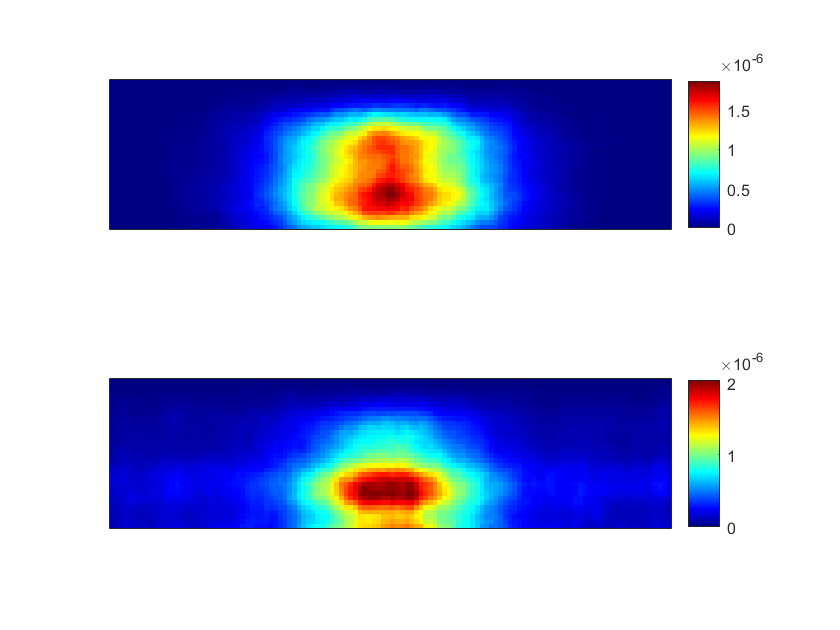

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(d22_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题

subplot(2,1,2);
% 可视化模拟数据
imagesc(d22_theo);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签

% 设置标题


- 评估误差

*to ljy:也许这里可以画两个饼图，一个是真实的一个时预测的*

% 上行、下行比例误差
U22_1=U22_1L+U22_1R;
U22_2=U22_2L+U22_2R;
r_up_esrimated=U22_1/(U22_1+U22_2); % 上行百分比
r_down_esrimated=U22_2/(U22_1+U22_2); % 下行百分比
ratio_esrimated=U22_1/U22_2 %上行：下行

ratio_esrimated = 1.3904


r_up_true=U22_1_true/(U22_1_true+U22_2_true); % 上行百分比
r_downp_true=U22_2_true/(U22_1_true+U22_2_true); % 下行百分比
ratio_true=U22_1_true/U22_2_true %上行：下行

ratio_true = 1.5021


% 磨损深度分布误差
e=d22_true-d22_theo;
e_norm=(sum(sum(abs(e))))/(sum(sum(d22_theo)));
disp(e_norm);

    0.3538



- 分布分析

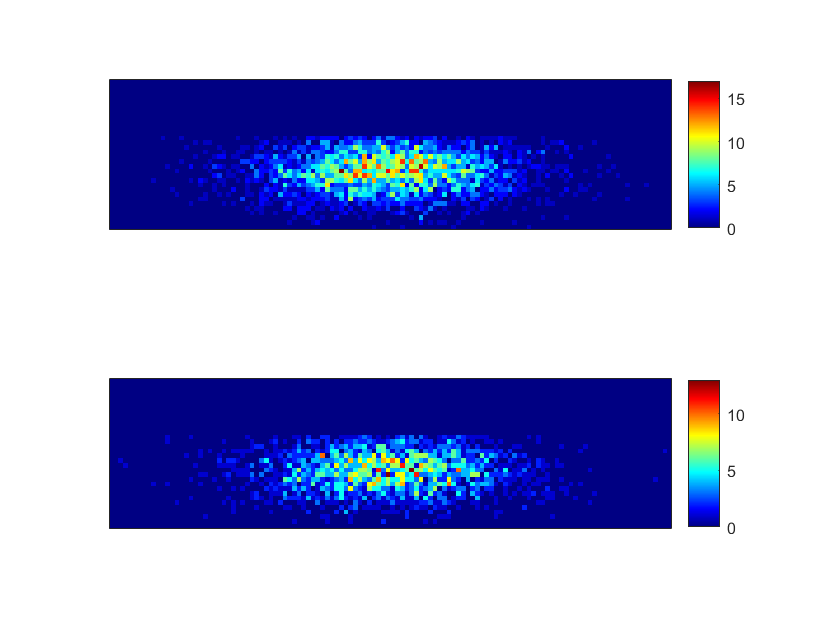

figure();
subplot(2,1,1);
imagesc(f22_1_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题

subplot(2,1,2);
imagesc(f22_2_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签

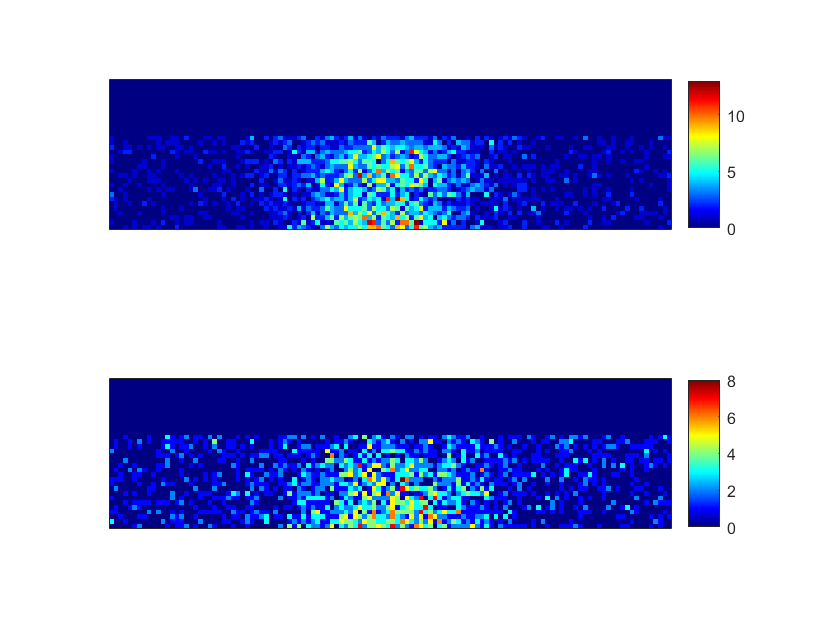

% 设置标题

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(f22_1);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题

subplot(2,1,2);
imagesc(f22_2);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签

% 设置标题


## **定量分析**

**有时候，为了简单判断上行，下行次数比例，可以通过总磨损量简单判断。**

**在一定总数的情况下，改变下行次数所占百分比，观察总磨损量**

*to ljy:这里建议画出点后，拟合一条直线*

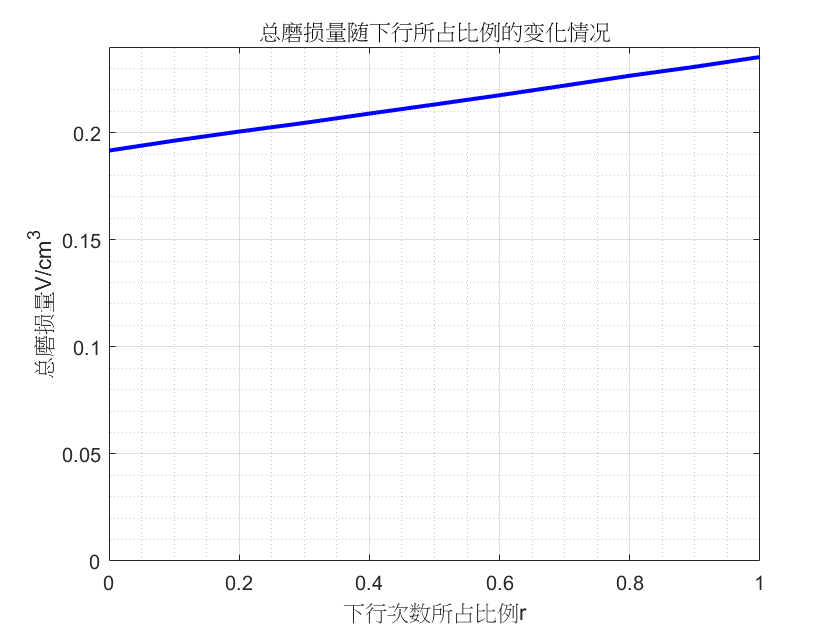

r = 0:0.1:1;% 下行所占比例
V = zeros(length(r),1);
for i=1:length(r)
    [d_true,temp1,temp2,temp3,temp4] = True(f_n,m,n,delta_S,r(i));
    V(i) = sum(sum(d_true))*delta_S;
end
figure();
plot(r,1e6*V','b','LineWidth',2);
grid on;grid minor;
ylim([0,0.24]);
xlabel('下行次数所占比例r');
ylabel('总磨损量V/cm^3');
title('总磨损量随下行所占比例的变化情况')

# **回答第三问**

只考虑两人并行的情况，台阶宽度有限。

f_n=6000;
load data_3.mat;
% 模拟真实数据
sum(dot3_true(:,3))/f_n

ans = 0.3782


[U3_1_true,U3_2_true,f3_1_true,f3_2_true]=True_Process(f_n,dot3_true,m,n);
[U3_1L,U3_1R,U3_2L,U3_2R,f3_1L,f3_1R,f3_2L,f3_2R]=Estimate_Process(f_n,f3_estimated,m,n);
f3_total_ture=f3_1_true+f3_2_true;
% 根据算法得到分布，并重建数据
d3_theo=d_calculate(m,n,delta_S,f3_1L,f3_1R,f3_2L,f3_2R);
f3_total=f3_1L+f3_1R+f3_2L+f3_2R;
f3_1=f3_1L+f3_1R;
f3_2=f3_2L+f3_2R;

- 对比【真实值】和【经过遗传算法得到分布后的重建值】

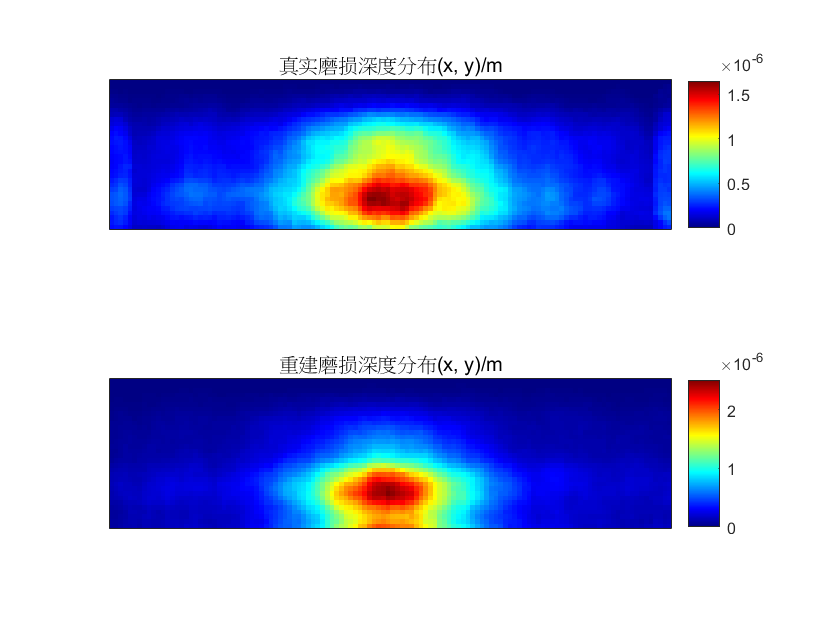

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(d3_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('真实磨损深度分布(x, y)/m');
subplot(2,1,2);
% 可视化模拟数据
imagesc(d3_theo);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('重建磨损深度分布(x, y)/m');

- 分析分布

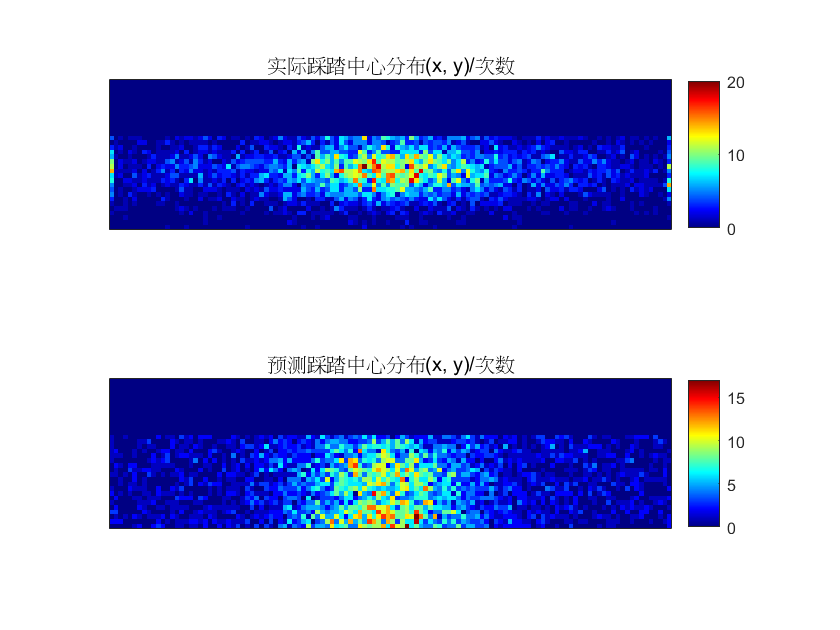

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(f3_total_ture);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('实际踩踏中心分布(x, y)/次数');
subplot(2,1,2);
imagesc(f3_total);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('预测踩踏中心分布(x, y)/次数');

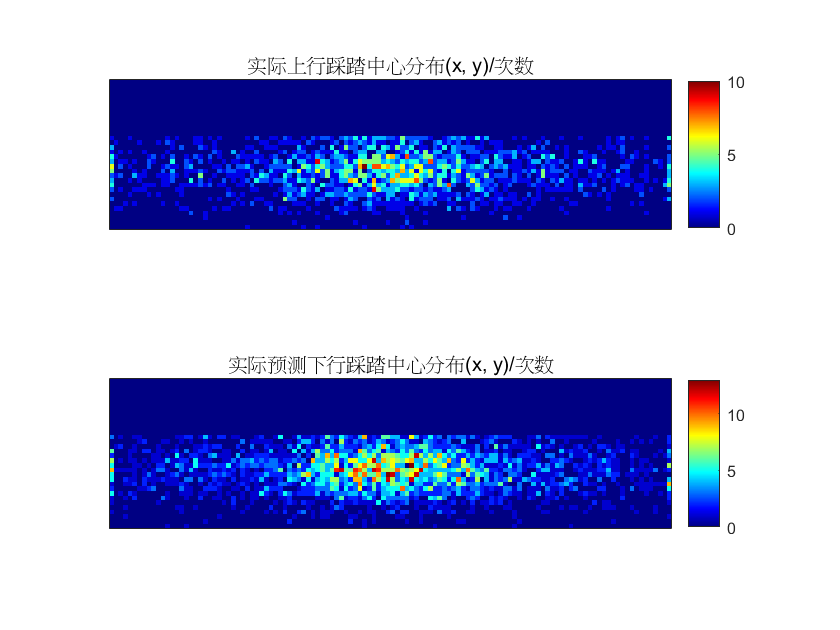

% 可视化模拟数据
figure();
subplot(2,1,1);
imagesc(f3_1_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('实际上行踩踏中心分布(x, y)/次数');
subplot(2,1,2);
imagesc(f3_2_true);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('实际预测下行踩踏中心分布(x, y)/次数');

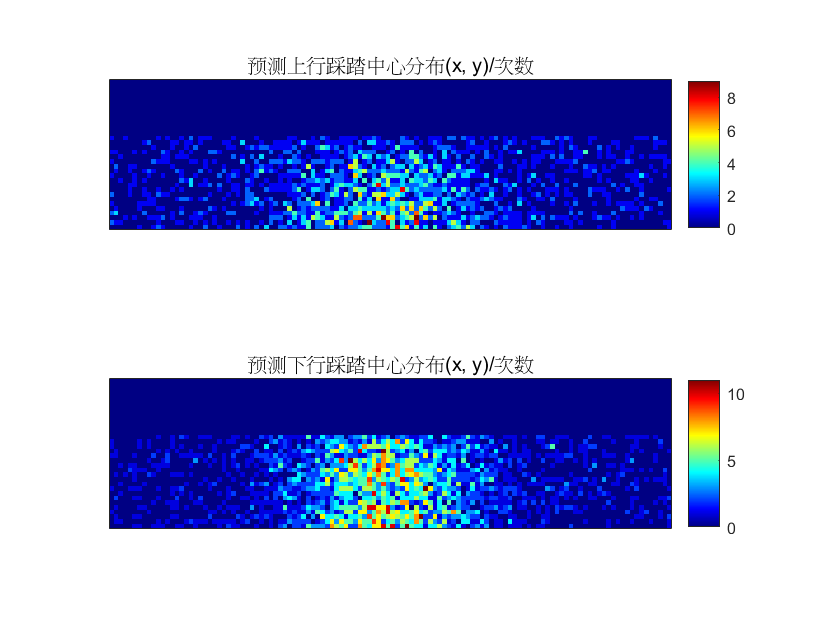

figure();
subplot(2,1,1);
imagesc(f3_1);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('预测上行踩踏中心分布(x, y)/次数');
subplot(2,1,2);
imagesc(f3_2);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
% caxis([0, 1000*180]);               % 设置颜色范围 [0, 1]
% 设置网格为方格
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
% 隐藏坐标轴刻度
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
% 设置标题
title('预测下行踩踏中心分布(x, y)/次数');

- 评估误差

***to ljy:也许这里可以画两个饼图，一个是真实的一个时预测的***

% 上行、下行比例误差
U3_1=U3_1L+U3_1R;
U3_2=U3_2L+U3_2R;
r_up_esrimated=U3_1/(U3_1+U3_2); % 上行百分比
r_down_esrimated=U3_2/(U3_1+U3_2); % 下行百分比
ratio_esrimated=U3_1/U3_2%上行：下行

ratio_esrimated = 0.6295

r_up_true=U3_1_true/(U3_1_true+U3_2_true); % 上行百分比
r_downp_true=U3_2_true/(U3_1_true+U3_2_true); % 下行百分比
ratio_true=U3_1_true/U3_2_true %上行：下行

ratio_true = 0.6081


% 重建分布误差
e=d3_true-d3_theo;
e_norm=(sum(sum(abs(e))))/(sum(sum(d3_theo)));
disp(e_norm);

    0.3157



- 对同时性进行分析

若在区间[40,80]内，算作独行；若在区间外，算作并行。由计算结果分析可得，在大多数的情况下，人们更倾向于独行。

***to ljy:这里你可以加一些指标或者图像***

counter=0;
for i=1:f_n
    if dot3_true(i,1)>30 && dot3_true(i,1)<90
        counter=counter+1;
    end
end
ratio_sim=(f_n-counter)/f_n;%并行比例
disp(ratio_sim);

    0.2380



- 计算理论磨损深度

function d_theo=d_calculate(m,n,delta_S,f_1L,f_1R,f_2L,f_2R)
load F.mat
d_theo = zeros(n,m);
for i=1:n
    for j=1:m
        d_theo = d_theo + alphal_1L(i,j,1,m,n,delta_S,F1L).*f_1L(33-i,j) + ...
            alphal_1R(i,j,1,m,n,delta_S,F1R).*f_1R(33-i,j) + ...
            alphal_2L(i,j,1,m,n,delta_S,F2L).*f_2L(33-i,j) + ...
            alphal_2R(i,j,1,m,n,delta_S,F2R).*f_2R(33-i,j);
    end
end
end

- 模拟真实数据

function [d_true,f_1_true,f_2_true,U_1_true,U_2_true]=True(f_n,m,n,delta_S,r_down)
%规定有0<=r_down<=1
r_down=r_down*10;
load F.mat;
rng(42);
dot_true = zeros(f_n, 4);
f_1_true=zeros(n,m);
f_2_true=zeros(n,m);
for i=1:f_n
    dot_true(i,1) = round(normrnd(m/2, m/8));
    dot_true(i,1) = min(max(dot_true(i,1), 1), m);  %确保值在 [1, m] 范围内


    dot_true(i,2) = round(normrnd(n/2-3, n/8));
    dot_true(i,2) = min(max(dot_true(i,2), 1), n-12);   %确保值在 [1, n-12] 范围内



    triger=0 + (10-0)*rand;
    if triger<r_down %下行
        dot_true(i,3)=0;
    else %上行
        dot_true(i,3)=1;
    end



    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if dot_true(i,3)==1 %上行
        f_1_true(33-dot_true(i,2),dot_true(i,1))=f_1_true(33-dot_true(i,2),dot_true(i,1))+1;
    elseif dot_true(i,3)==0 %下行
        f_2_true(33-dot_true(i,2),dot_true(i,1))=f_2_true(33-dot_true(i,2),dot_true(i,1))+1;
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


    dot_true(i,4) = randi([0, 1]);% 1-左脚，0-右脚
end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
U_1_true=sum(sum(f_1_true));
U_2_true=sum(sum(f_2_true));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



d_true = zeros(n, m);
for i = 1:f_n
    if dot_true(i,3)&&dot_true(i,4) %上行，左脚
        d_true = d_true + alphal_1L(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F1L);
    elseif dot_true(i,3)&&(~dot_true(i,4)) %上行，右脚
        d_true = d_true + alphal_1R(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F1R);
    elseif (~dot_true(i,3))&&dot_true(i,4) %下行，左脚
        d_true = d_true + alphal_2L(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F2L);
    elseif (~dot_true(i,3))&&(~dot_true(i,4)) %下行，右脚
        d_true = d_true + alphal_2R(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F2R);
    end
end
end